clear;

A = [2 0 -4 2;
    0 2 -2 4;
    -4 -2 2 0;
    2 4 0 2];
B = [8 0;
    6 0;
    4 0;
    2 0];
C = [2 0 0 2;
    -1 1 1 1];
D = [0 3; 0 2];

x0 = [1; 1; 1; 1];
xh0 = [0; 0; 0; 0];
nu = 1;


%===Stability====

U = [B A*B A^2*B A^3*B];
ru = rank(U);
%disp("ru");
%disp(ru);

%===Observation==

V = [C; C*A; C*A^2; C*A^3];
rv = rank(V);
%disp("rv");
%disp(rv);

%=======Q==&==R========

Qk =eye(4)*10;
Rk = eye(2);

QL = [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];
%QL = QL * 0.01;
RL = [0.5 0; 0 0.5];
%RL = RL * 0.01;

%=======K=============

[Pk,~,K2] = icare(A, B, Qk, Rk, 0, eye(4), 0);

disp("Determinant of Pk");

Determinant of Pk


disp(det(Pk));

   6.9983e+03




disp("Pk");

Pk


disp(Pk);

  339.3214 -195.0494 -294.1131 -156.0911
 -195.0494  117.0442  163.9014   89.6462
 -294.1131  163.9014  261.6570  135.1953
 -156.0911   89.6462  135.1953   75.0003




K = -pinv(Rk) * B' * Pk;

%[K,P,eigs] = lqr(A,B,Qk,Rk,[]);
%K = -K;

disp("K");

K


disp(K);

  -55.6401   23.2323   52.4779   20.0700
         0         0         0         0




disp("A+BK checking");

A+BK checking


disp(eig(A+B*K));

  -35.0536
   -6.9641
   -4.0000
   -1.6581



%=======L=============
[PL,~,K1] = icare(A', C', QL, RL, 0, eye(4), 0);

disp("Determinant of PL");

Determinant of PL


disp(det(PL));

    0.1893




disp("PL");

PL


disp(PL);

    0.9091    0.5297   -1.0234    0.2904
    0.5297    1.8822   -1.2636    1.0234
   -1.0234   -1.2636    1.8822   -0.5297
    0.2904    1.0234   -0.5297    0.9091




L = -PL* C' * pinv(RL);
%G = diag([1 0 3 -1]);
%N = [1 0; 0 1; 1 0; 0 1];
%[L,P,E] = lqe(A,G,C,QL,RL,N);
disp("L");

L


disp(L);

   -4.7979    2.2247
   -6.2121   -2.2247
    6.2121   -2.2247
   -4.7979   -2.2247



disp("A+LC checking");

A+LC checking


disp(eig(A+L*C));

   -8.5431
   -2.6486
   -4.8990
   -4.0000




zero(ss(A, B, C, D))

ans =    3.4286 + 2.5555i
   3.4286 - 2.5555i
  -4.0000 + 0.0000i


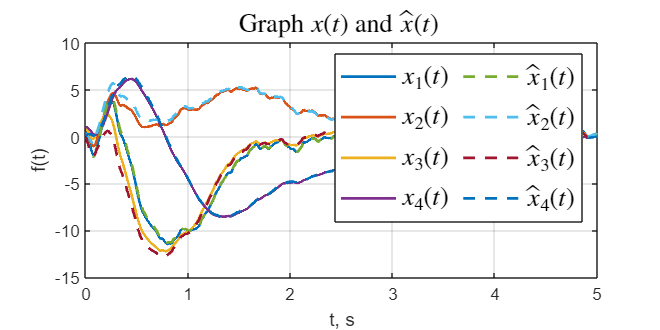


%[K,~,~] = lqr(A,B,Qk,Rk); % Синтез регулятора
%[L,~,~] = lqe(A,eye(4),C,QL,RL); % Синтез наблюдателя
%====Modeling=======

open_system('task_3_simm');
set_param('task_3_simm/x', 'VariableName', 'x')
set_param('task_3_simm/xh', 'VariableName', 'xh')
set_param('task_3_simm/e', 'VariableName', 'e')

out = sim('task_3_simm');

figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
hold on
plot(out.xh,'--', 'LineWidth',1.5);

grid()
title('Graph $x(t)$ and $\hat{x}(t)$ ','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', '$x_4(t)$', ...
    '$\hat{x}_1(t)$', '$\hat{x}_2(t)$', '$\hat{x}_3(t)$', '$\hat{x}_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off

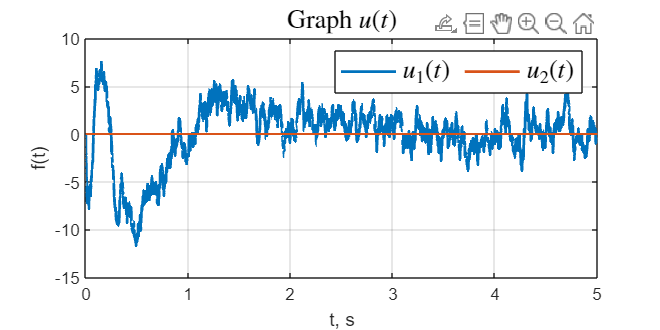



plot(out.u,'-', 'LineWidth',1.5);

grid()
title('Graph $u(t)$','Interpreter','latex',  'FontSize', 14)
legend('$u_1(t)$', '$u_2(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

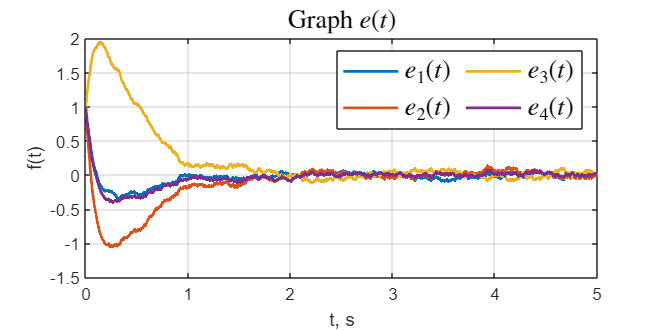



plot(out.e,'-', 'LineWidth',1.5);

grid()
title('Graph $e(t)$','Interpreter','latex',  'FontSize', 14)
legend('$e_1(t)$', '$e_2(t)$', '$e_3(t)$', '$e_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')